# 2주차 과제 — 모델링과 전달함수

**제어시스템설계** · 충남대학교 자율운항시스템공학과

문제는 **세 개**입니다.

- **1. 몸풀기** (쉬움 · 수업 중 10분 · 30점) — 댐퍼만 바꿔 극점을 따라가기

- **2. 기본** (중간 · 40분 · 70점) — RC 회로를 모델링해 응답까지

- **3. 도전** (선택 · 가산점 10점) — 영점을 하나 붙이면

**3번은 선택입니다.** 1번과 2번만 해도 만점입니다.

제출

- 이 파일을 복사해 `W02_HW_학번_이름.mlx` 로 저장하고 빈칸을 채워 제출

- 그림에는 축 이름과 범례를 넣을 것

clc; close all;
s = tf('s');

## 1. 몸풀기 — 댐퍼를 세게 하면 극점이 어디로 가나

**강의노트 9절을 그대로 보면 됩니다.** 거기 있는 코드에서 댐퍼 값만 바꿉니다.

질량-스프링-댐퍼의 전달함수입니다.


$$G(s) = \frac{1}{m s^2 + b s + k}, \qquad m = 1,\; k = 1$$


댐퍼 $b$ 만 바꿔 가며 **극점이 어디로 가는지**, 그때 **응답이 어떻게 변하는지** 봅니다.

할 일

- 아래 코드에서 `TODO` 두 줄만 채우십시오

쓸 명령 (전부 강의노트 7절에 있습니다)

- `pole(G)` — 극점

- `damp(G)` — 감쇠비와 고유진동수를 한 번에

맞았는지 확인하는 법

- $b = 2$ 일 때 극점이 $-1$ 두 개로 겹치면 맞은 것입니다 (임계감쇠)

b_list = [0.2 1.0 2.0 3.0];

fprintf('    b     극점                        감쇠비   고유진동수\n');
fprintf('  -----  --------------------------  ------  ----------\n');
for b = b_list
    G = 1/(s^2 + b*s + 1);
    p_  = NaN;    % TODO : pole(G) 로 극점을 구하십시오
    [wn_, z_] = deal(NaN, NaN);   % TODO : [wn_, z_] = damp(G) 로 구하십시오
    if numel(p_) == 2
        fprintf('  %5.1f  %-26s  %6.3f  %10.3f\n', b, ...
                mat2str(round(p_(:).', 3)), z_(1), wn_(1));
    else
        fprintf('  %5.1f  (아직 안 채움)\n', b);
    end
end

## 1-1. 그림으로 확인

코드는 다 되어 있습니다. 실행만 하면 됩니다.

t1 = (0:0.02:20)';
tiledlayout(1,2,'TileSpacing','compact');

nexttile
hold on; grid on;
for b = b_list
    G = 1/(s^2 + b*s + 1);
    pl = pole(G);
    plot(real(pl), imag(pl), 'x', 'MarkerSize', 12, 'LineWidth', 2, ...
         'DisplayName', sprintf('b = %.1f', b));
end
xline(0, 'k-'); yline(0, 'k-');
xlabel('실수부'); ylabel('허수부');
title('댐퍼를 키우면 극점이 실축으로 모인다');
legend('Location','best');

nexttile
hold on; grid on;
for b = b_list
    plot(t1, step(1/(s^2 + b*s + 1), t1), 'LineWidth', 2, ...
         'DisplayName', sprintf('b = %.1f', b));
end
yline(1, 'k--', 'HandleVisibility', 'off');
xlabel('시간 [s]'); ylabel('출력');
title('그때 응답은 이렇게 변한다');
legend('Location','southeast');

## 1-2. 답할 것 (두 문장이면 됩니다)

- $b$ 를 키우면 극점은 어느 방향으로 움직이는가?

- 그때 응답의 **진동**은 어떻게 되는가?

## 2. 기본 — RC 회로를 모델링해 보기

**강의노트 2절의 네 단계를 그대로 밟으면 됩니다.**

- 1단계 물리 법칙 → 2단계 미분방정식 → 3단계 라플라스 → 4단계 전달함수

회로는 이렇습니다. 저항 $R$ 과 커패시터 $C$ 가 직렬로 있고, 입력은 전체 전압 $v_{in}$, 출력은 커패시터 양단 전압 $v_C$ 입니다.

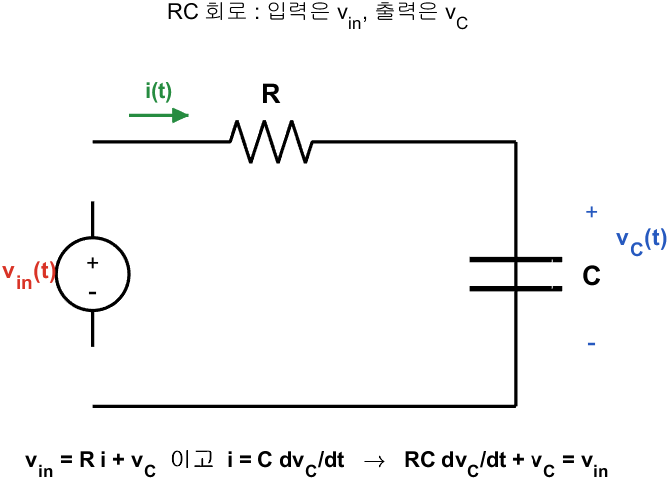

RC 회로 : 입력은 v_in, 출력은 v_C

**그림 파일** `rc_circuit.png` — `common/dg_rc.m` 의 `dg_rc` · 다시 만들려면 `make_figures('rc_circuit')`

## 2-1. 손으로 하는 부분

아래 세 줄을 손으로 채워 보십시오 (계산은 아주 짧습니다).

- **1단계** 저항의 전압은 $R\,i$, 커패시터의 전류는 $i = C\,\frac{dv_C}{dt}$

- **2단계** 키르히호프 전압 법칙을 쓰면 미분방정식이 나옵니다


$$v_{in} = R\,i + v_C = \; ?$$


- **3단계** 초기값을 $0$ 으로 두고 라플라스 변환하면


$$V_{in}(s) = \; ?$$


- **4단계** 정리하면 전달함수가 나옵니다


$$G(s) = \frac{V_C(s)}{V_{in}(s)} = \; ?$$


힌트 : 답은 $\frac{1}{\tau s + 1}$ 꼴입니다. $\tau$ 가 무엇인지 찾으면 됩니다.

## 2-2. MATLAB 으로 확인

손으로 구한 $\tau$ 를 아래에 넣으십시오.

값은 $R = 1\,\mathrm{k\Omega}$, $C = 100\,\mu\mathrm{F}$ 로 합니다.

R_ = 1e3;
C_ = 100e-6;

tau_ = NaN;    % TODO : 손으로 구한 시정수를 R_ 과 C_ 로 쓰십시오
G_rc = NaN;    % TODO : 1/(tau_*s + 1) 로 전달함수를 만드십시오

if isa(G_rc, 'tf')
    fprintf('\nRC 회로\n');
    G_rc
    fprintf('  극점 : %.3f\n', pole(G_rc));
    fprintf('  시정수 tau = %.3f s\n', tau_);
    fprintf('  DC 이득 = %.3f\n', dcgain(G_rc));
end

## 2-3. 응답을 먼저 예측하고, 그다음 확인

1차 시스템은 숫자 하나($\tau$)면 전부 알 수 있습니다.

- 정착시간 (2 % 기준) $\approx 4\tau$

- $t = \tau$ 일 때 최종값의 약 $63\%$ 에 도달

- 오버슈트 없음

먼저 **손으로 예측**한 뒤 아래 코드로 확인하십시오.

if isa(G_rc, 'tf')
    t2 = (0:0.001:0.8)';
    y2 = step(G_rc, t2);
    info2 = stepinfo(G_rc);

    fprintf('\n  예측 (4*tau) : %.3f s\n', 4*tau_);
    fprintf('  실측 정착시간 : %.3f s\n', info2.SettlingTime);
    fprintf('  t = tau 에서의 값 : %.3f  (예측 0.632)\n', ...
            interp1(t2, y2, tau_));

    plot(t2, y2, 'LineWidth', 2); hold on;
    yline(1, 'k--'); yline(0.632, 'r:');
    xline(tau_, 'r:'); grid on;
    xlabel('시간 [s]'); ylabel('v_C [V]');
    legend('응답', '최종값', '63 % 선 / t = \tau', 'Location', 'southeast');
    title('1차 시스템은 시정수 하나로 전부 설명된다');
end

## 2-4. 답할 것 (세 문장이면 됩니다)

- 시정수 $\tau$ 는 얼마인가? 단위까지 쓰라

- $C$ 를 $10$ 배로 키우면 응답은 빨라지는가 느려지는가? 왜인가?

- 이 회로의 극점은 하나뿐이다. 그렇다면 **진동할 수 있는가?**

## 3. 도전 (선택) — 영점을 하나 붙이면

**이 문제는 선택입니다. 안 해도 만점입니다.** 가산점 10점입니다.

강의노트 11절에서 영점이 응답을 바꾼다는 것을 보았습니다. 여기서는 영점 위치를 직접 바꿔 봅니다.


$$G(s) = \frac{s + z}{s^2 + 0.6\,s + 1}$$


할 일

- $z = 0.5,\ 2,\ 10$ 세 경우의 계단응답을 한 그림에 겹쳐 그려라

- 세 응답을 DC 이득으로 나눠 정규화해서 그려야 공평하다

- 오버슈트를 `stepinfo` 로 재어 표로 적어라

답할 것 (두 문장)

- 영점이 **원점에 가까울수록** 오버슈트는 커지는가 작아지는가?

- 극점은 하나도 안 건드렸는데 왜 응답이 달라지는가?

TODO : 여기에 코드를 작성하십시오

## 채점 기준

- **1. 몸풀기** 30점 — 표를 채웠는가, 두 질문에 답했는가

- **2. 기본** 70점 — 네 단계 유도, MATLAB 확인, 세 질문에 답했는가

- **3. 도전** 가산점 10점

감점 사항 (세 가지뿐입니다)

- 축 이름이나 범례가 없는 그림

- 손 유도 과정 없이 답만 적은 경우

- 코드가 오류로 멈추는 경우